% =========================================================================
%  Real test realization
%  Author: Yago Lizarribar
% =========================================================================
clear; clc; close all; warning ('off','all');

% Speed of light
global c; %m/s
c = 299792458;

% adds subfolder with functions to PATH
% [p,n,e] = fileparts(mfilename('fullpath'));
p = pwd;
addpath([p '/tdoa']);
addpath([p '/ltess']);
addpath([p, '/geodesy']);

%% Load configuration
filename = 'real_tests/locations_dab_dab.json';
problem_data = json_load(filename);

% Sensors
NUM_SENSORS = length(problem_data.sensors);
NUM_FILES_SENSOR = problem_data.config.files_per_sensor;

folder_location = '/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/data/real_tests';
localization_files = cell(NUM_SENSORS, NUM_FILES_SENSOR);
ltess_files = cell(NUM_SENSORS, NUM_FILES_SENSOR);

sensors = zeros(NUM_SENSORS, 3);
distances_rs = zeros(NUM_SENSORS,1);
distances_us = distances_rs;

us_lat = problem_data.transmitters.unknown.coord(1);
us_lon = problem_data.transmitters.unknown.coord(2);
us_hei = 800;

for ii = 1:NUM_SENSORS
    sensors(ii,1:2) = problem_data.sensors(ii).coordinates;
    sensors(ii,3) = problem_data.sensors(ii).height;
end

## Coordinate Transformation 

center = mean(sensors,1);

[xEast(1), yNorth(1), zUp(1)] = geodetic2enu(sensors(1,1), sensors(1,2), sensors(1,3), center(1), center(2), center(3), wgs84Ellipsoid);
[xEast(2), yNorth(2), zUp(2)] = geodetic2enu(sensors(2,1), sensors(2,2), sensors(2,3), center(1), center(2), center(3), wgs84Ellipsoid);
[xEast(3), yNorth(3), zUp(3)] = geodetic2enu(sensors(3,1), sensors(3,2), sensors(3,3), center(1), center(2), center(3), wgs84Ellipsoid);
[xEast(4), yNorth(4), zUp(4)] = geodetic2enu(sensors(4,1), sensors(4,2), sensors(4,3), center(1), center(2), center(3), wgs84Ellipsoid);

xEast = xEast';
yNorth = yNorth';
zUp = zUp';

[xUnknown, yUnknown, zUnknown] = geodetic2enu(us_lat, us_lon, us_hei, center(1), center(2), center(3), wgs84Ellipsoid);

% Computing DOP
xrange = (-8000:20:10000); N = length(xrange);
yrange = (-6000:20:8000); M = length(yrange);

hdop = zeros(M,N);
edop = zeros(M,N);
ndop = zeros(M,N);

for ii = 1:length(xrange)
    for jj = 1:length(yrange)
        xpos = xrange(ii); ypos = yrange(jj); zpos = 0;
        R = sqrt(sum(([xEast, yNorth] - [xpos, ypos]).^2,2));
        
        A = [(xEast - xpos)./R, (yNorth - ypos)./R, ones(4,1)];
        Q = (A'*A)\eye(size(A,2));
        
        hdop(jj,ii) = sqrt(Q(1,1)^2 + Q(2,2)^2);
        edop(jj,ii) = Q(1,1);
        ndop(jj,ii) = Q(2,2);
        
    end
end

hdop(hdop > 200) = 200;
edop(edop > 200) = 200;
ndop(ndop > 200) = 200;

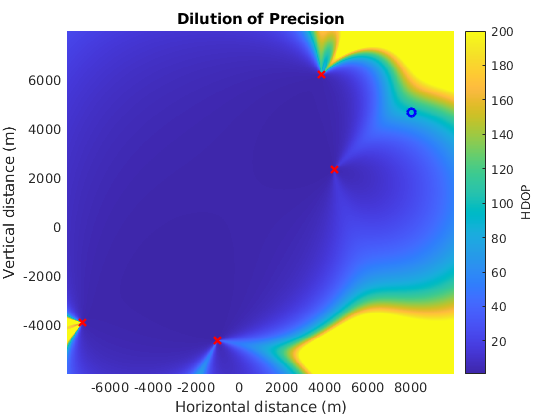

figure();
hold on;
set(gca,'TickLength',[0 0]);
imagesc(xrange,yrange,hdop);
plot(xEast,yNorth,'rx','LineWidth',2);
plot(xUnknown,yUnknown,'bo','LineWidth',2);

xlim([-7999,9999]); ylim([-5999, 7999]);
cl = colorbar;
cl.Label.String = 'HDOP';
title('Dilution of Precision');
xlabel('Horizontal distance (m)');
ylabel('Vertical distance (m)');
hold off;

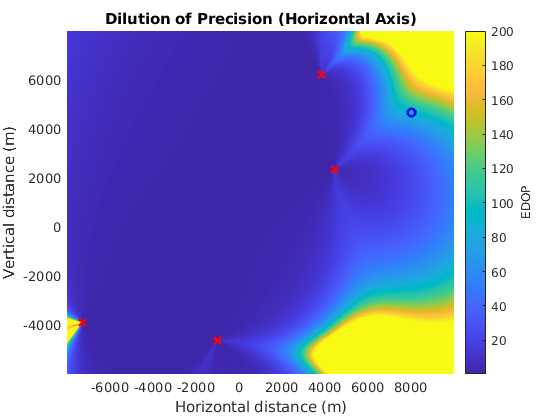

figure();
hold on;
set(gca,'TickLength',[0 0])
imagesc(xrange,yrange,edop);
plot(xEast,yNorth,'rx','LineWidth',2);
plot(xUnknown,yUnknown,'bo','LineWidth',2);

xlim([-7999,9999]); ylim([-5999, 7999]);
cl = colorbar;
cl.Label.String = 'EDOP';
title('Dilution of Precision (Horizontal Axis)');
xlabel('Horizontal distance (m)');
ylabel('Vertical distance (m)');
hold off;

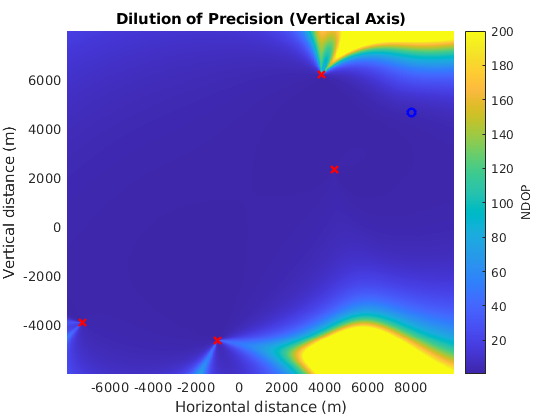

figure();
hold on;
set(gca,'TickLength',[0 0])
imagesc(xrange,yrange,ndop);
plot(xEast,yNorth,'rx','LineWidth',2);
plot(xUnknown,yUnknown,'bo','LineWidth',2);

xlim([-7999,9999]); ylim([-5999, 7999]);
cl = colorbar;
cl.Label.String = 'NDOP';
title('Dilution of Precision (Vertical Axis)');
xlabel('Horizontal distance (m)');
ylabel('Vertical distance (m)');
hold off;

sensors(5,:) = [40.43807224681118, -3.6380405810723646, 600];
sensors(6,:) = [40.39007832171968, -3.645708228783774, 600];

xEastm = xEast; yNorthm = yNorth; zUpm = zUp;
[xEastm(5), yNorthm(5), zUpm(5)] = geodetic2enu(sensors(5,1), sensors(5,2), sensors(5,3), center(1), center(2), center(3), wgs84Ellipsoid);
[xEastm(6), yNorthm(6), zUpm(6)] = geodetic2enu(sensors(6,1), sensors(6,2), sensors(6,3), center(1), center(2), center(3), wgs84Ellipsoid);

% Computing DOP
xrange = (-9000:20:11000); N = length(xrange);
yrange = (-6000:20:8000); M = length(yrange);

hdopm = zeros(M,N);
edopm = zeros(M,N);
ndopm = zeros(M,N);

for ii = 1:length(xrange)
    for jj = 1:length(yrange)
        xpos = xrange(ii); ypos = yrange(jj); zpos = 0;
        R = sqrt(sum(([xEastm, yNorthm] - [xpos, ypos]).^2,2));
        
        A = [(xEastm - xpos)./R, (yNorthm - ypos)./R, ones(6,1)];
        Q = (A'*A)\eye(size(A,2));
        
        hdopm(jj,ii) = sqrt(Q(1,1)^2 + Q(2,2)^2);
        edopm(jj,ii) = Q(1,1);
        ndopm(jj,ii) = Q(2,2);
        
    end
end

hdopm(hdopm > 30) = 30;
edopm(edopm > 30) = 30;
ndopm(ndopm > 30) = 30;

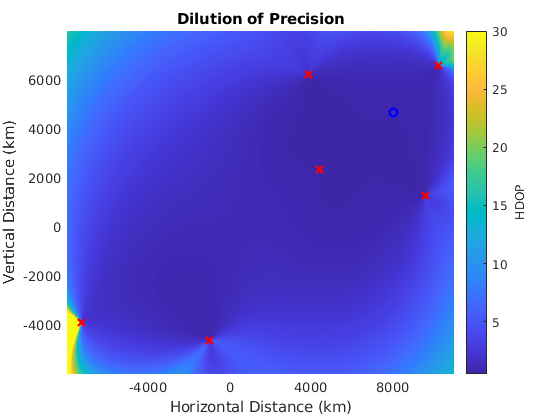

figure();
hold on;
set(gca,'TickLength',[0 0])
imagesc(xrange,yrange,hdopm);
plot(xEastm,yNorthm,'rx','LineWidth',2);
plot(xUnknown,yUnknown,'bo','LineWidth',2);

xlim([-7999,10999]); ylim([-5999, 7999]);
cl = colorbar;
cl.Label.String = 'HDOP';
title('Dilution of Precision');
xlabel('Horizontal Distance (km)');
ylabel('Vertical Distance (km)')
hold off;

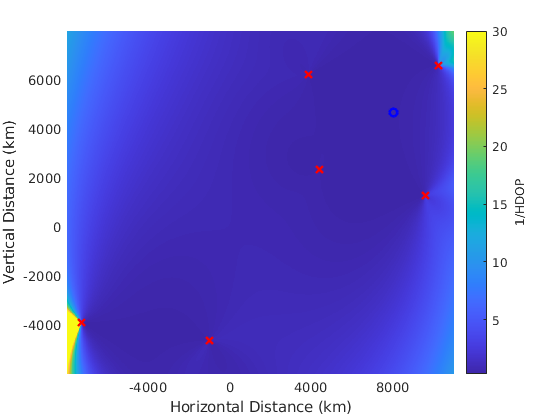

figure();
hold on;
set(gca,'TickLength',[0 0])
imagesc(xrange,yrange,edopm);
plot(xEastm,yNorthm,'rx','LineWidth',2);
plot(xUnknown,yUnknown,'bo','LineWidth',2);

xlim([-7999,10999]); ylim([-5999, 7999]);
cl = colorbar;
cl.Label.String = '1/HDOP';
xlabel('Horizontal Distance (km)');
ylabel('Vertical Distance (km)')
hold off;

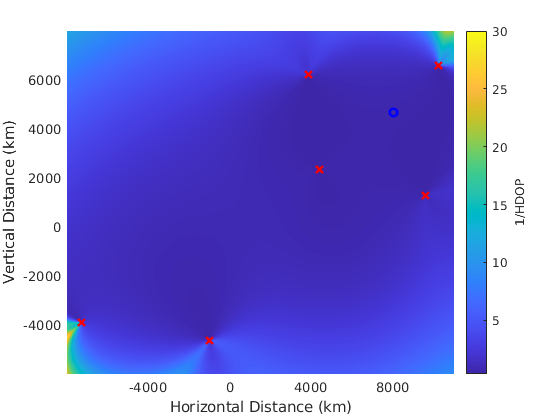

figure();
hold on;
set(gca,'TickLength',[0 0])
imagesc(xrange,yrange,ndopm);
plot(xEastm,yNorthm,'rx','LineWidth',2);
plot(xUnknown,yUnknown,'bo','LineWidth',2);

xlim([-7999,10999]); ylim([-5999, 7999]);
cl = colorbar;
cl.Label.String = '1/HDOP';
xlabel('Horizontal Distance (km)');
ylabel('Vertical Distance (km)')
hold off;